# Introduction

Implementation of Spiliopoulos' inter-bank reserve model with common noise


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}\widetilde{W}^{i}_{t} $$


where $\mathrm{~d}\widetilde{W}^{i}_{t} := \rho \mathrm{d}W_t^0 + \sqrt{1-\rho^2} \mathrm{~d}W_t^i$, with $W^{i}$ the individual noises and $W^{0}$ the common noise and $|\rho| \leq 1$

# Baseline

Homogeneous banks ($a = 1, \sigma = 1$), no common noise


$$\mathrm{d}X_t^i = \left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \mathrm{~d}W^{i}_{t}$$


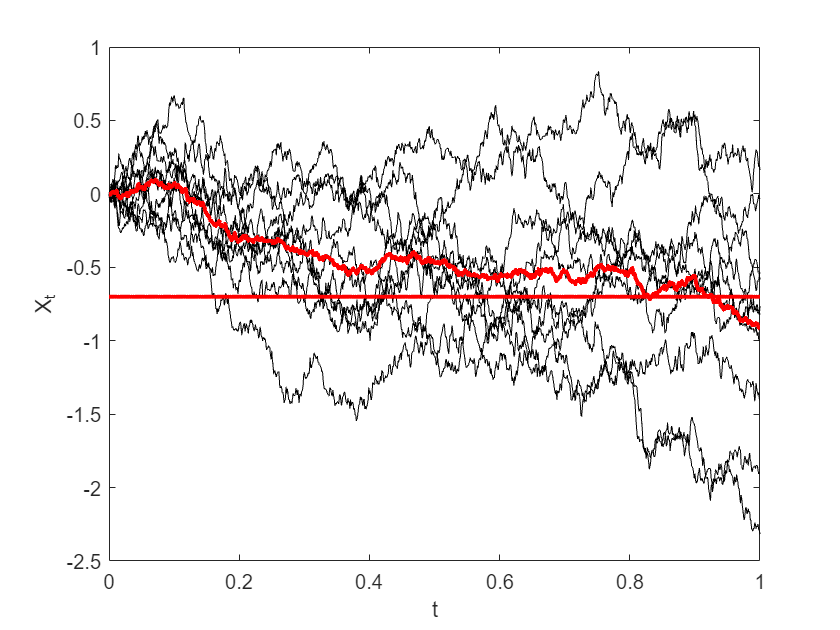

baseline = model(ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
plot_trajectory(baseline);

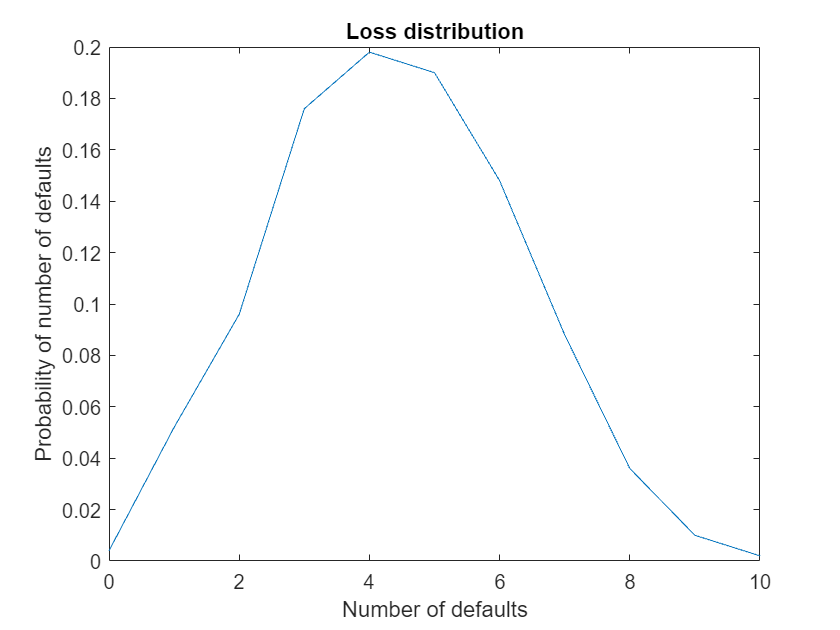

plot_loss(baseline);

# Homogeneous, common-noise


$$\mathrm{d}X_t^i = \left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \mathrm{~d}\widetilde{W}^{i}_{t}$$


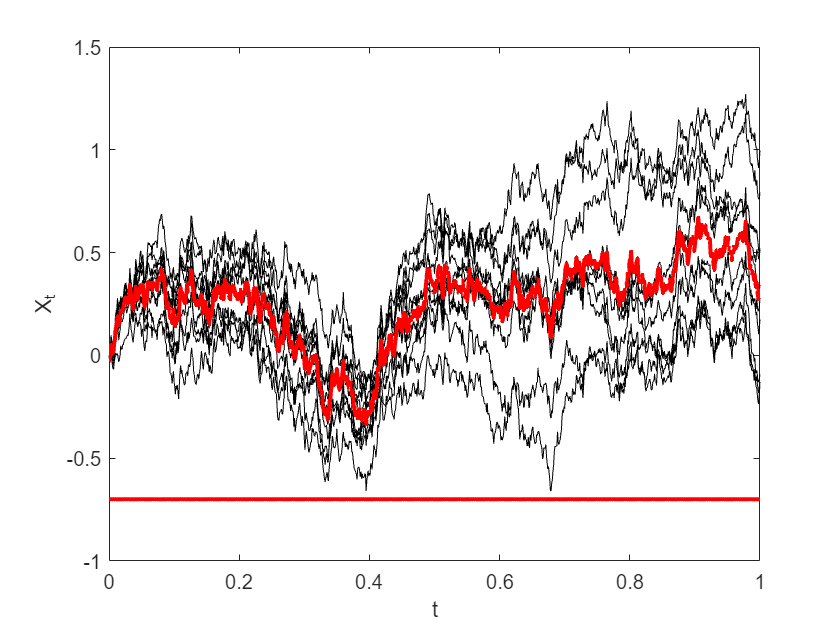

baseline_cn = baseline.common_noise(0.9);
baseline_cn = baseline_cn.sde_euler;
baseline_cn.plot_trajectory;

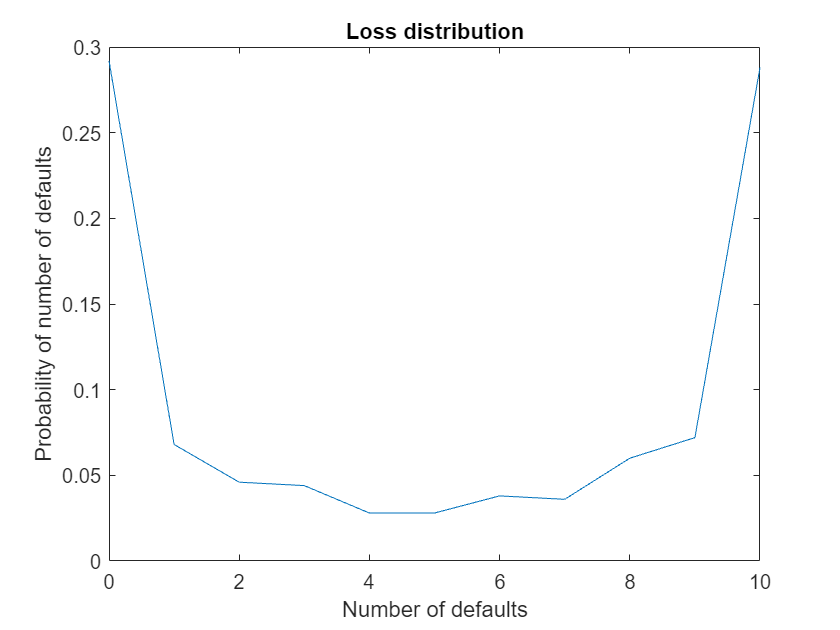

baseline_cn.plot_loss;

# Group A


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t} $$



$$\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


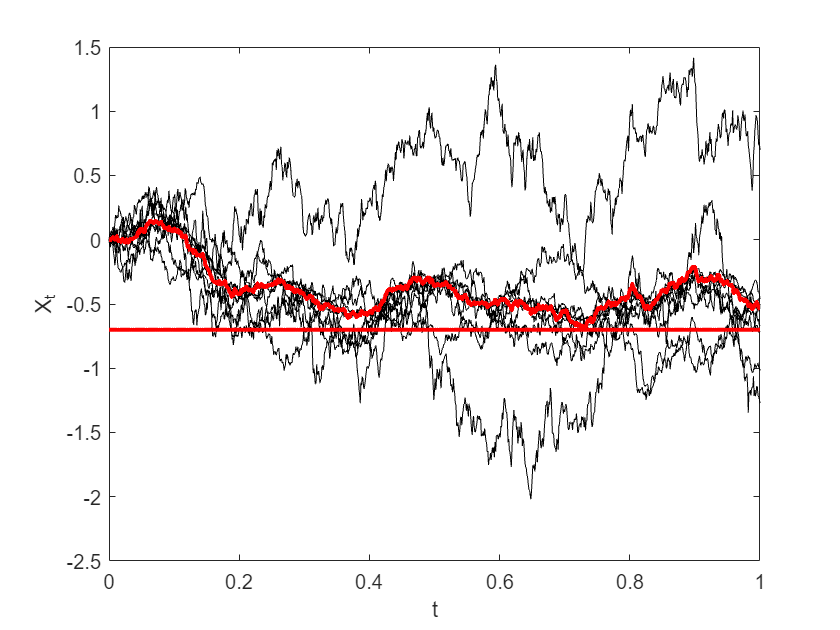

model_A = model( ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
model_A = model_A.sde_euler;
model_A.plot_trajectory;

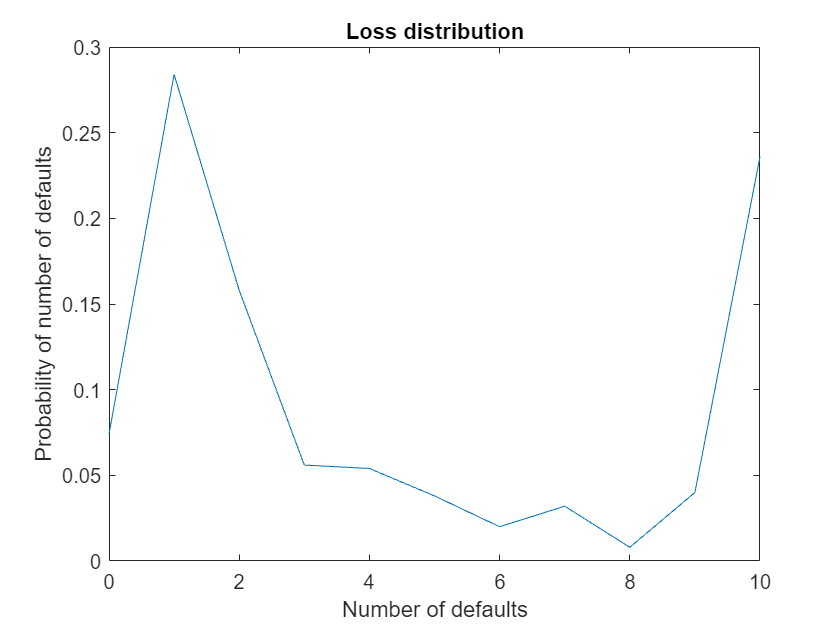

model_A.plot_loss;

# Group A with common noise


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}\widetilde{W}^{i}_{t} $$



$$\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


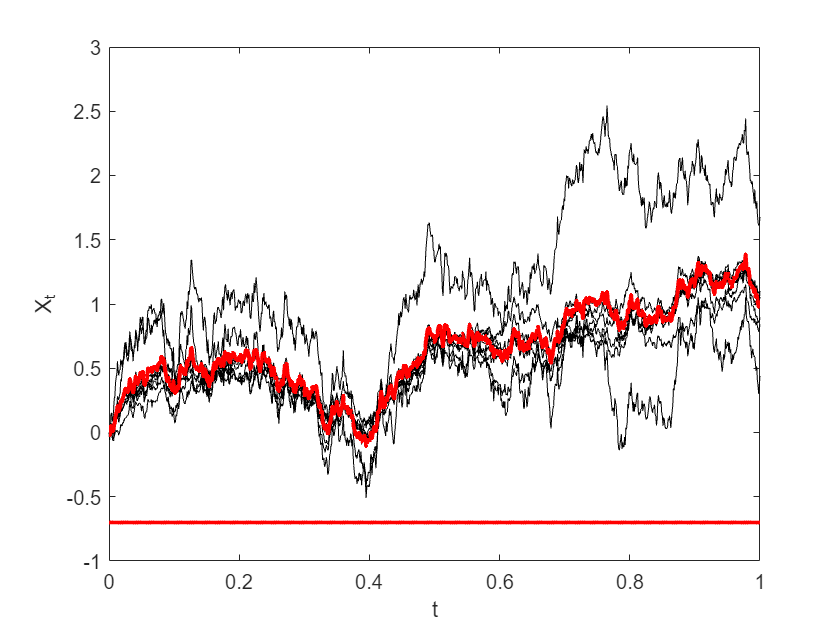

model_A_cn = model_A.common_noise(0.9);
model_A_cn = model_A_cn.sde_euler;
model_A_cn.plot_trajectory;

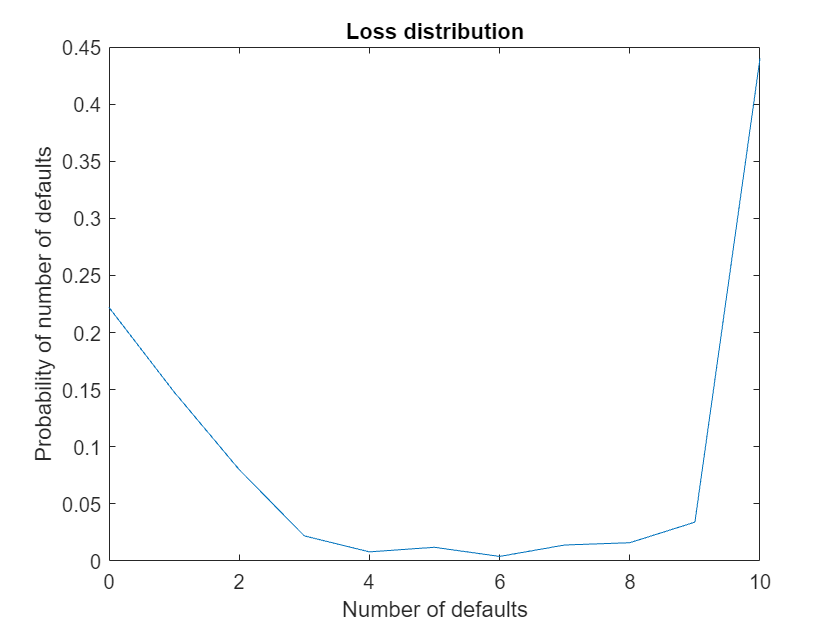

model_A_cn.plot_loss;